# Cours 16 11 22 interpolation

## interpolation polynomiale

clear; clc; close all;

x = [-2 -1 1 2] % position x des points

x =     -2    -1     1     2


y = [10 4 6 3] % position y des points

y =     10     4     6     3



% Tools -> Basic fitting -> Types of fit : cubic
% R^2 : definit comment la courbe passe bien par les points
% RMSE : erreurs residus
% On veut faire ceci automatiquement ...

% On construit la matrice de Vandermonde
% Construction manuelle :
V = [-8 4 -2 1;
    -1 1 -1 1;
    1 1 1 1;
    8 4 2 1];

% Construction avec les points d'intrepolation
% Plus rapide ainsi de construire V
x = x';
V = [x.^3 x.^2 x.^1 x.^0]

V =     -8     4    -2     1
    -1     1    -1     1
     1     1     1     1
     8     4     2     1



% On veut maintenant resoudre Vc = y
%y = y'; % Transpose (et conjugue si complexe)
y = y(:); % Convertit en vecteur colonne (pas de chemin inverse)
c = V\y

c =    -0.9167
    0.5000
    1.9167
    4.5000


a = c(1); b = c(2); d = c(4); c = c(3);

% Dessiner le polynome
% p(x) = ax^3 + bx^2 + cx + d
p = @(x) a*x^3 + b*x^2 + c*x + d

p = function_handle with value:
    @(x)a*x^3+b*x^2+c*x+d


ezplot(p, [-3 3]); hold on; 

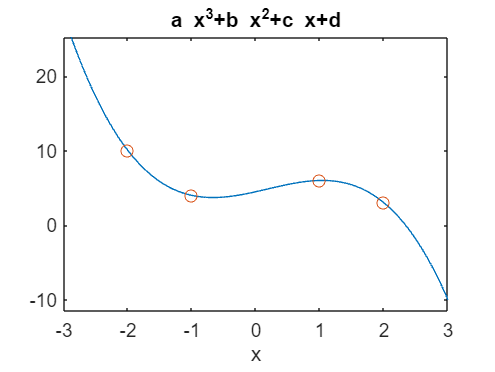

plot(x, y, 'o'); hold off;

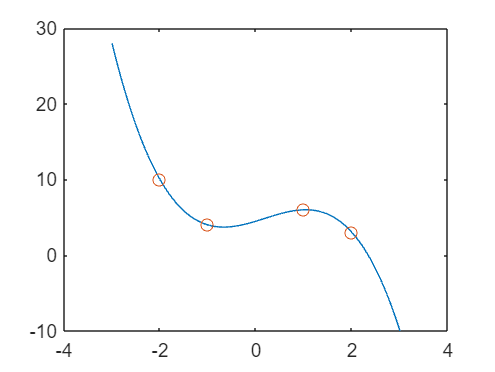

% Autre facon de dessiner le polynome
xx = linspace(-3, 3, 1e3); % 1000 points entre -3 et 3
p = a*xx.^3 + b*xx.^2 + c*xx + d;
plot(xx , p); hold on; 
plot(x, y, 'o'); hold off;


% Meilleure facon de dessiner le polynome,
% pour eviter d'ecrire le polynome entier.
% On va utiliser la commande polyval
c = V\y % c est le vecteur des coefficient du polynome

c =    -0.9167
    0.5000
    1.9167
    4.5000


xx = linspace(-3, 3, 1e3); % 1000 points entre -3 et 3
p = polyval(c, xx); % quel que soit c. Du coeff le plus eleve au plus bas
plot(xx, p); hold on;
plot(x, y, 'o'); hold off;


% La fonction vander
x = x(:)

x =     -2
    -1
     1
     2


vander(x)

ans =     -8     4    -2     1
    -1     1    -1     1
     1     1     1     1
     8     4     2     1


x = [x; 5]

x =     -2
    -1
     1
     2
     5


vander(x)

ans =     16    -8     4    -2     1
     1    -1     1    -1     1
     1     1     1     1     1
    16     8     4     2     1
   625   125    25     5     1


## La fonction polyfit

clear; clc; close all;

x = [-2 -1 1 2]

x =     -2    -1     1     2


y = [10 4 6 3]

y =     10     4     6     3


% Utilistion du polyfit au lieu de vander(x) et V\y
% Il fait tout. Il demande le degré comme parametre
c = polyfit(x, y, length(x)-1)

c =    -0.9167    0.5000    1.9167    4.5000


polyval(c, -5)

ans = 122.0000

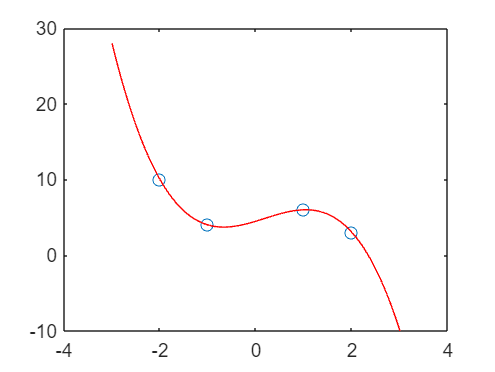


xx = linspace(-3, 3, 1e3);
p = polyval(c, xx);
plot(x, y, 'o', xx, p, 'r'); % Plot de deux graphes en une fois